max_profit = 1:20;
competition = 1:20;

% Calculating h_i(x_i), i.e. maximum return with cost lambda on
% advertisement

advertisement_allocations = zeros(20,101,101);
% each z-index is the lambda values, which will scale from 0 to 10
% each row is different activities, each column is the amount of production
% each entry gives the advertisement budget that generates maximum return
% under its associated linear cost with coefficient lambda

advertisement_returns = zeros(20,101,101);
% same setup with allocations
% each entry gives the maximum return under each number of production and 
% each associated linear cost with coefficient lambda


for lambda = 0:0.1:10

    % for the current value of lambda, we will obtain the optimal
    % advertisement investment per each activity with its cost, under 
    % fixed production numbers
    for activity = 1:20
        
        % calculate the optimal advertisement allocation for x much 
        % production investment
        for x = 0:100
    
            max_return = 0;
            optimal_adv = 0;
    
            for y = 0:1000

                a = competition(activity)/(x+y); % the exponent on e
                if x==y && x==0
                    fprintf(num2str(a))
                end
                b = (-1)*a;
                c = exp(b);
                d = (1-c)^x;
                e = (1-d);
                f = max_profit(activity)*e;
                g = f - lambda*y;
    
                

                if g > max_return
                    max_return = g;
                    optimal_adv = y;
                end

            end

            lambda_equivalent = cast(10*lambda + 1,"uint8");

            advertisement_allocations(activity,x+1,lambda_equivalent) = optimal_adv;
            advertisement_returns(activity,x+1,lambda_equivalent) = max_return;


        end        
    end
end

InfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfInfI


% allocations for various total production budgets x with cost 0.2 per unit
% advertisement cost
advertisement_allocations(17,:,3)

ans =      0    27    25    21    17    14    11     9     7     5     4     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% allocations on all activities for a fixed production with a cost
advertisement_allocations(:,10,2)

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     1


sum(advertisement_allocations(:,10,2)) % this is equal to the advertisement budget

ans = 63

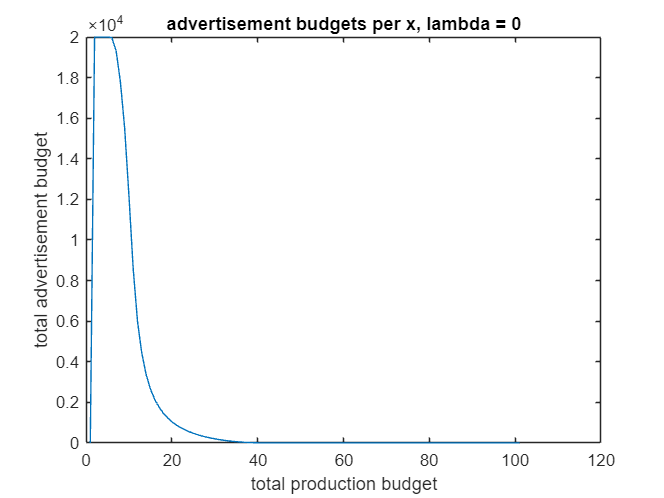

% for lambda = 0.1

% when lambda = 1.8, the total advertisement budget is zero

adv_budgets_1 = zeros(1,101);
for x = 1:101

    adv_budgets_1(x) = sum(advertisement_allocations(:,x,1));
    % total expenditure on advertising over all departments with zero cost
    % for a total of x much production budget

end
plot(adv_budgets_1)
title("advertisement budgets per x, lambda = 0")
xlabel("total production budget")
ylabel("total advertisement budget")

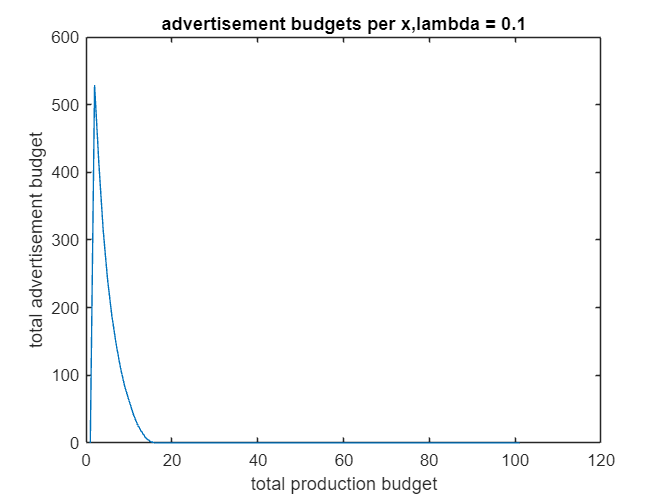


adv_budgets_2 = zeros(1,101);
for x = 1:101

    adv_budgets_2(x) = sum(advertisement_allocations(:,x,2));

end
plot(adv_budgets_2)
title("advertisement budgets per x,lambda = 0.1")
xlabel("total production budget")
ylabel("total advertisement budget")

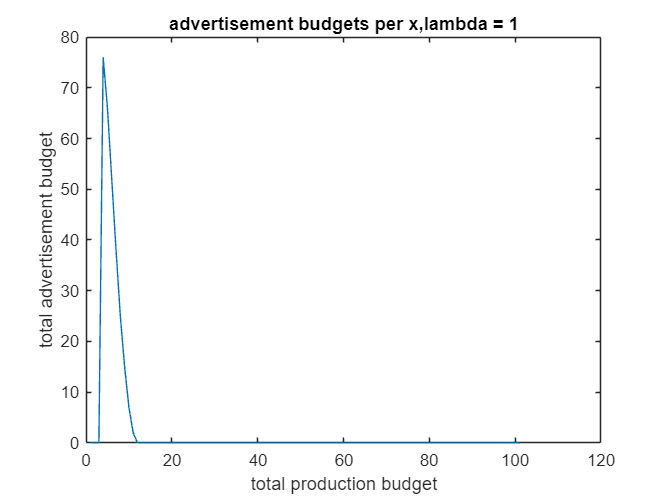


adv_budgets_3 = zeros(1,101);
for x = 1:101

    adv_budgets_3(x) = sum(advertisement_allocations(:,x,11));

end
plot(adv_budgets_3)
title("advertisement budgets per x,lambda = 1")
xlabel("total production budget")
ylabel("total advertisement budget")

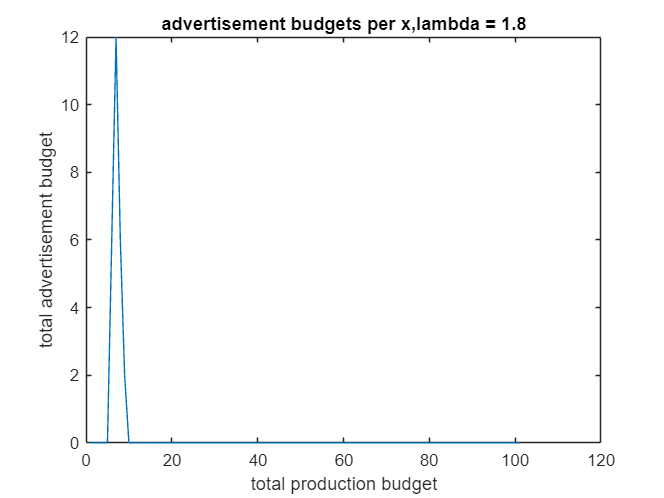


adv_budgets_4 = zeros(1,101);
for x = 1:101

    adv_budgets_4(x) = sum(advertisement_allocations(:,x,19));

end
plot(adv_budgets_4)
title("advertisement budgets per x,lambda = 1.8")
xlabel("total production budget")
ylabel("total advertisement budget")


% Recall for 
% each z-index is the lambda values, which will scale from 0 to 10
% each row is different activities, each column is the amount of production
% each entry gives the advertisement budget that generates maximum return
% under its associated linear cost with coefficient lambda

% from the plots we see that the advertisement budget goes
% down as both lambda, i.e. the cost of advertisement, and x, i.e.
% the production investment goes up.

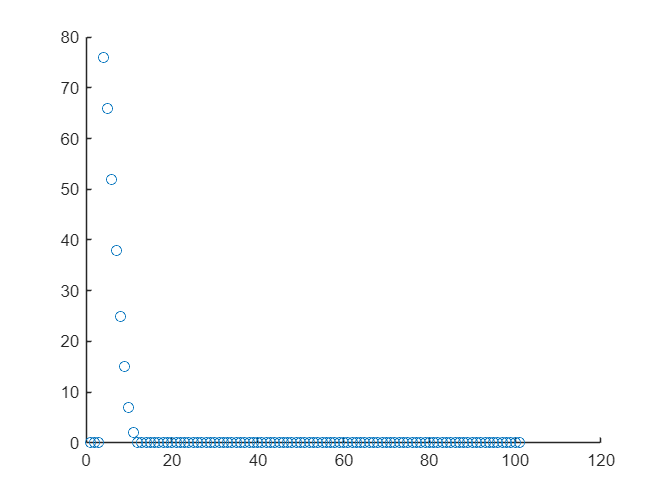


scatter(1:101,adv_budgets_3)

#### Solution Steps For Optimal Production Choices

% for a particular lambda we will do a one-stage allocation process, where
% allocations will happen with the optimal advertisement investments
% already figured out
lambda = 19; 


% we will obtain a vector of length 20 for each different total production budgets,
% that shows how much production investment should go to each activity, 
% and the outcomes of those vectors as well


optimal_productions = zeros(101,20,20);
% rows are total production budgets
% columns are different activities
% z-index is for different stages of the process


optimal_returns = zeros(101,20);
% rows are total production budgets
% columns are different stages


% obtain the correct outcomes of each activity
activity_returns = advertisement_returns(:,:,lambda);
% each row is different activities, from 1 to 20, and each column is different
% production investments to that activity, from zero to 100



% stage = 1
for budget = 0:100
   
    % only the first activity is considered, so all the budget is expended
    % on the first activity
    stage_1_return = activity_returns(1,budget+1);
    stage_1_allocation = zeros(1,20);
    stage_1_allocation(1) = budget;

    % place the optimal return and allocation into the optimal_returns and
    % optimal_productions matrices

    optimal_returns(budget+1,1) = stage_1_return;
    optimal_productions(budget+1,:,1) = stage_1_allocation;
end

%stage = 2

for budget = 0:100
    
    % we will choose how much to invest on the second activity, and the
    % rest of the budget will go to the first activity. 
    return_with_investment = 0;
    prod_allocation = zeros(1,20);
    
    for investment = 0:budget
        
        % invest the investment into the second activity
        current_activity_return = activity_returns(2,investment+1);
        remaining_budget_return = optimal_returns(budget+1-investment,1);
        investment_return = current_activity_return + remaining_budget_return; 
        
        if investment_return > return_with_investment
            % attribute the new return into the check variable
            return_with_investment = investment_return;
            
            % obtain the production allocation for remaining budget
            dummy_allocation = optimal_productions(budget+1-investment,:,1);

            % add the new investment to second activity on top of the
            % allocation done by the remaining budget, 
            dummy_allocation(2) = dummy_allocation(2) + investment;

            % finally, put this allocation into the check variable
            prod_allocation = dummy_allocation;
        end

    end

    % we obtained the max return and the right allocation on second stage,
    % and stored it in the variables "return_with_investment" and
    % "prod_allocation". Now, put these into the matrices that hold the
    % optimal allocations and returns.

    optimal_returns(budget+1,2) = return_with_investment;
    optimal_productions(budget+1,:,2) = prod_allocation;

end


% remaining stages
for stage = 3:20
    
    for budget = 0:100
    
        % we will choose how much to invest on the second activity, and the
        % rest of the budget will go to the first activity. 
        return_with_investment = 0;
        prod_allocation = zeros(1,20);
        
        for investment = 0:budget
            
            % invest the investment into the second activity
            current_activity_return = activity_returns(stage,investment+1);
            remaining_budget_return = optimal_returns(budget+1-investment,stage-1);
            investment_return = current_activity_return + remaining_budget_return; 
            
            if investment_return > return_with_investment
                % attribute the new return into the check variable
                return_with_investment = investment_return;
                
                % obtain the production allocation for remaining budget
                dummy_allocation = optimal_productions(budget+1-investment,:,stage-1);
    
                % add the new investment to second activity on top of the
                % allocation done by the remaining budget, 
                dummy_allocation(stage) = dummy_allocation(stage) + investment;
    
                % finally, put this allocation into the check variable
                prod_allocation = dummy_allocation;
            end
    
        end
    
        % we obtained the max return and the right allocation on second stage,
        % and stored it in the variables "return_with_investment" and
        % "prod_allocation". Now, put these into the matrices that hold the
        % optimal allocations and returns.
    
        optimal_returns(budget+1,stage) = return_with_investment;
        optimal_productions(budget+1,:,stage) = prod_allocation;

    end
    
end

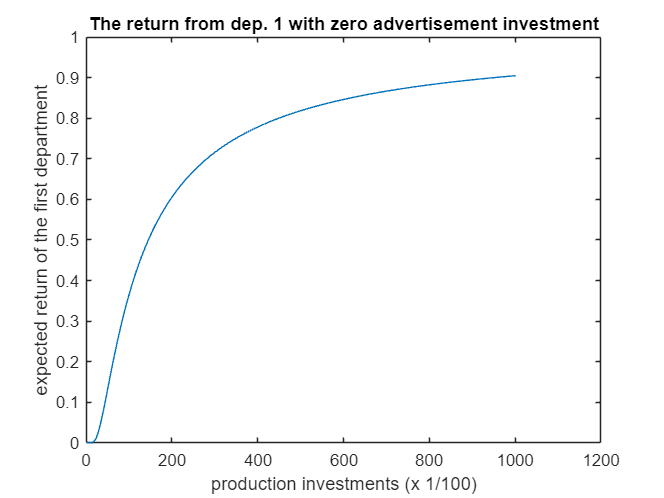

p = 0:0.01:10;
q = 1*(1 - (1 - exp((-1)./(p)))); 

plot(q)
title("The return from dep. 1 with zero advertisement investment")
xlabel("production investments (x 1/100)")
ylabel("expected return of the first department")

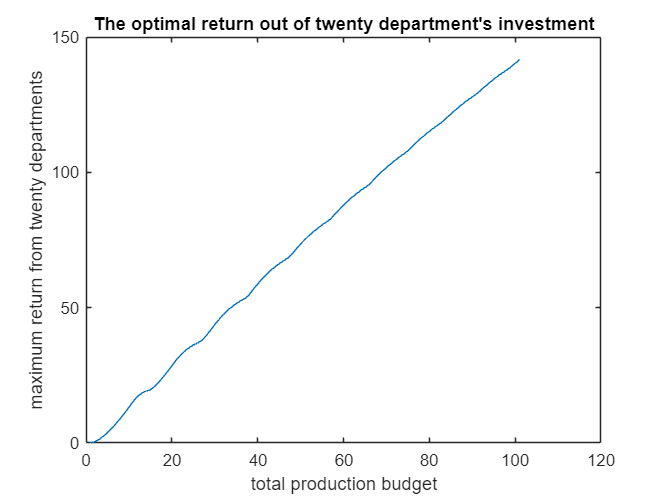



plot(optimal_returns(:,20))
title("The optimal return out of twenty department's investment")
xlabel("total production budget")
ylabel("maximum return from twenty departments")



optimal_productions(51, :, 20)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     9    10    10    10    11


optimal_productions(76, :, 20)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     8     8     9     9    10    10    10    11


optimal_productions(101, :, 20)

ans =      0     0     0     0     0     0     0     0     0     7     7     8     8     9     9    10    10    10    11    11



optimal_returns(51,20)

ans = 75.1505

optimal_returns(76,20)

ans = 109.5811

optimal_returns(101,20)

ans = 141.6464